# 基于无需标定相机的方式直接对普通广角/超广角/鱼眼视频做BEV

崔星星 2023.5.23

Email: cuixingxing150@gmail.com

使用实际地下停车场视频为例，因为是无标定方式，唯一先验知识需要从视频场景图像中估计相机内外参、畸变中心和畸变系数，包括图像中的直线，平行线，物体几何尺寸长宽等，精度取决于这些几何量选取或者检测的精度。 其**优势在于不适合或者不方便进行相机标定的场合，比如视频提供者只有提供的环视畸变视频。**

本文暂且实现单个前视环视图的BEV图像，因为其他视角情况大同小异，如果可同时提供前后左右四个环视图，还可以进一步扩展做全局拼接视图的BEV图像。

## 导入数据

使用以下ffmpeg命令把h264视频数据转换为无损jpg图像。

load ../data/preSavedData/data_caoji_ok1.mat% 包含以畸变图像中的直线信息去畸变的表格M,此数据集来源于自研开发的APP
imds = imageDatastore("/opt_disk2/rd22946/AllDataAndModels/from_caoji/front_fisheye");% 无损原始h264视频数据集

## 对含有一定几何信息的图像去畸变

假如我们发现视频中第1440帧的地面停车黄色标志线有长度和宽度信息，故读入此原始畸变图。

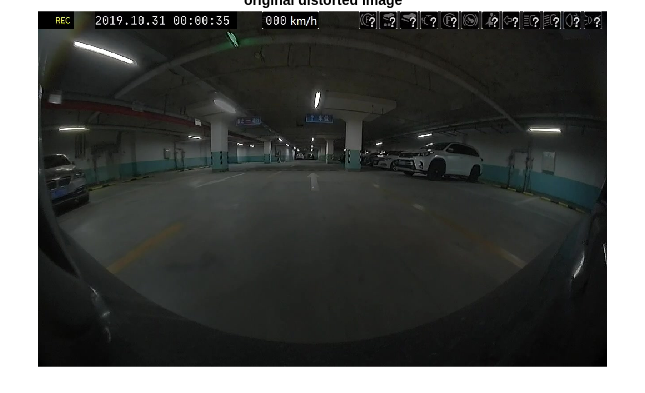

distortedImage = readimage(imds,1440);
figure;imshow(distortedImage);title("original distorted image")

使用自研的APP矫正存储的结果M表格用于计算去畸变

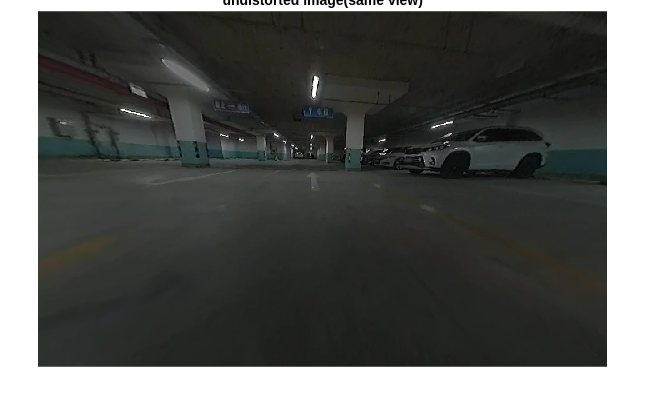

[undistortedImg,mapX,mapY] = robustRectifyImage(distortedImage,M,OutputView="same");
figure;imshow(undistortedImg);title("undistorted image(same view)")

if ~isfile("../data/preSavedData/birdsEye.mat") % 避免反复手动绘制，没有则重新绘制已知ROI宽度和高度的信息即可
    figure
    imshow(undistortedImg);
    title("Adjust the trapezoid ROI to select rectangular lane region, press Enter to continue");
    vertices = [size(undistortedImg,2)/2 size(undistortedImg,1)/2;...
        size(undistortedImg,2)/2 size(undistortedImg,1)*3/4;...
        size(undistortedImg,2)*3/4 size(undistortedImg,1)*3/4;...
        size(undistortedImg,2)*3/4 size(undistortedImg,1)/2];
    roi = drawpolygon(Position=vertices,FaceAlpha=0.2,LineWidth=1);

    % Wait until Enter is pressed
    wasButtonPressed = false;
    while ~wasButtonPressed
        wasButtonPressed = waitforbuttonpress;
        if double(get(gcf,"currentcharacter")) ~= 13
            wasButtonPressed = false;
        end
    end

    rectangleWidth = 3.6;% 猜测
    rectangleLength = 8; % 猜测
    imageSize = size(undistortedImg,[1,2]);
    [pitch,yaw,roll,height,intrinsicsOut] = estimateMonoCameraFromScene(roi.Position,rectangleWidth,rectangleLength,imageSize);


## 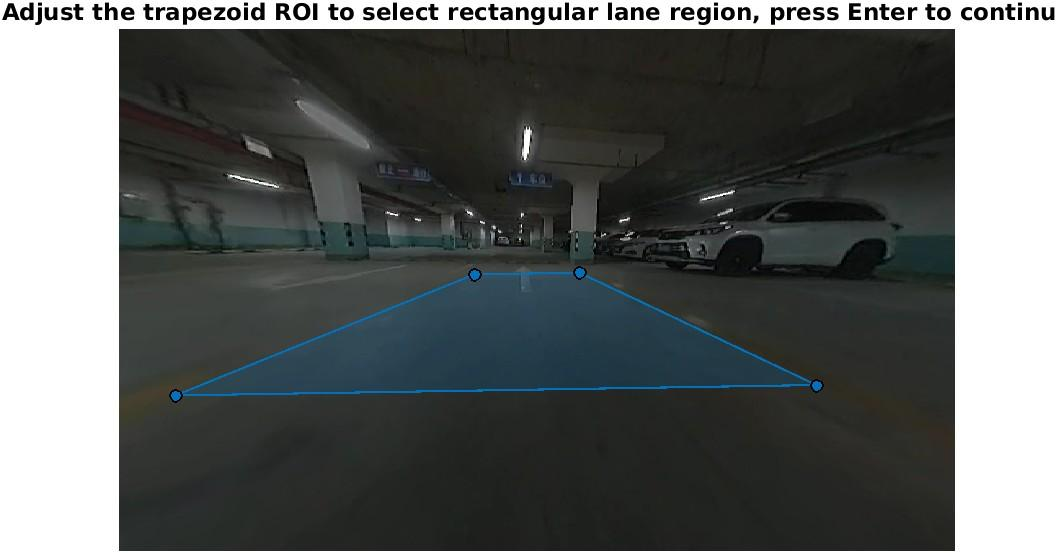

## 无畸变图转BEV

利用上述估计的镜头内外参数，构建birdsEyeView对象[3]，其本质上就是个保存相机内外参和一些鸟瞰图预定义超参的结构体，方便做鸟瞰图投影，设置好自己想看到的可视范围outView和图像大小outImageSize，然后对无畸变图undistortedImg直接做俯视投影，即为BEV图像。

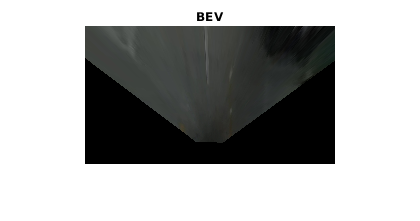

    sensor = monoCamera(intrinsicsOut,height,Pitch=pitch,Roll=roll,Yaw=yaw);
    distAhead = 10;% 前置摄像头光心到前面距离10m可视化范围内
    spaceToOneSide = 10;% 前置摄像头两侧各偏置10m可视化
    bottomOffset = -1;% 前置摄像头光心向后偏置1m可视化
    outView = [bottomOffset,distAhead,-spaceToOneSide,spaceToOneSide];
    outImageSize = [NaN 250];
    birdsEye = birdsEyeView(sensor,outView,outImageSize);
    BEV = transformImage(birdsEye,undistortedImg);
    imshow(BEV);title("BEV")
    save ../data/preSavedData/birdsEye.mat birdsEye
else
    load ../data/preSavedData/birdsEye.mat
end

## 视频批量转换BEV

上述图像“手动标定”觉得OK后，再批量对视频图像进行去畸变、bev处理即可。

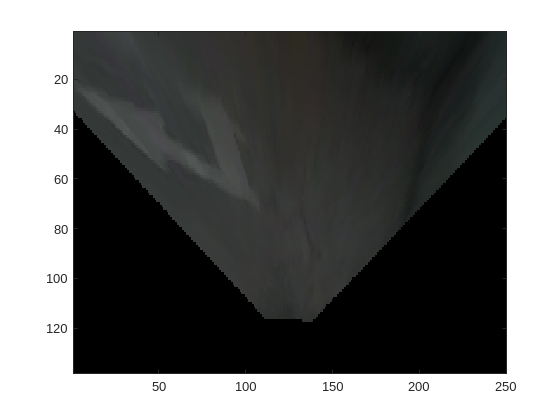

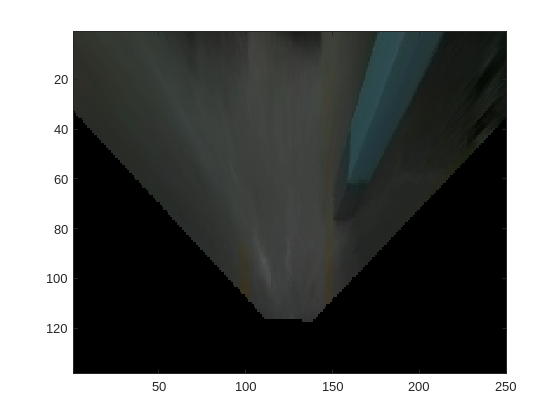

% v = VideoWriter('result.avi');
% v.FrameRate =50;
% open(v)
fg = figure(Name="BEV");
currAxes = axes(fg);
for i = 1:5:length(imds.Files)
    distortedImage = readimage(imds,i);
    undistortedImg = images.internal.interp2d(distortedImage,mapX,mapY,"linear",0, false);
    bevImg = transformImage(birdsEye,undistortedImg);
    % writeVideo(v,bevImg);

    image(bevImg, 'Parent', currAxes);
    pause(0.01);
end

% close(v);


## References:

[1] Xiaochen He and Nelson Hon Ching Yung. "New method for overcoming ill-conditioning in vanishing-point-based camera calibration." Optical Engineering 46(3),037202,2007.

[2] G. Fung, N. Yung, and G. Pang. "Camera calibration from road lane markings." Optical Engineering 42(10), 2003.

[3] [birdsEyeView](https://ww2.mathworks.cn/help/driving/ref/birdseyeview.html) 

[4] [how can i extract a good quality jpeg image from an h264 video file with ffmpeg](https://qastack.cn/programming/10225403/how-can-i-extract-a-good-quality-jpeg-image-from-an-h264-video-file-with-ffmpeg)